# ICE 6: Pole Placement

A = [-6 -11 -6; 1 0 0; 0 1 0];
B = [1; 0; 0];
C = [0 1 1.5];

ORSys = ss(A, B, C, 0);
ORTF = tf(ORSys)

ORTF =
 
         s + 1.5
  ----------------------
  s^3 + 6 s^2 + 11 s + 6
 
Continuous-time transfer function.
Model Properties


poles = pole(ORSys)

poles =    -3.0000
   -2.0000
   -1.0000


zeroes = zero(ORSys)

zeroes = -1.5000

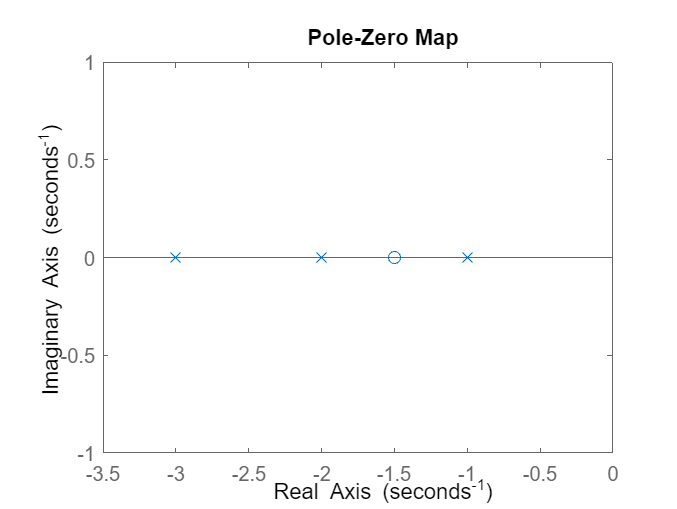

pzmap(ORSys)

zeta = sqrt(2)/2

zeta = 0.7071

w_n = 2*sqrt(2)

w_n = 2.8284

p = w_n

p = 2.8284

d0 = (w_n^2)*p

d0 = 22.6274

d1 = 2*zeta*w_n*p + w_n^2

d1 = 19.3137

d2 = 2*zeta*w_n + p

d2 = 6.8284

DesPoles = roots([1 d2 d1 d0])

DesPoles =   -2.8284 + 0.0000i
  -2.0000 + 2.0000i
  -2.0000 - 2.0000i


s_1 = -zeta*w_n + 1i*w_n*sqrt(1-zeta^2)

s_1 = -2.0000 + 2.0000i

K = acker(A, B, DesPoles)

K =     0.8284    8.3137   16.6274


CG = 1/(C*inv(-A+B*K)*B)

CG = 15.0849

r = 1 % unit step

r = 1

x_init = 0 % zero IC

x_init = 0

out = sim('ICE_6_SVF.slx', 6);

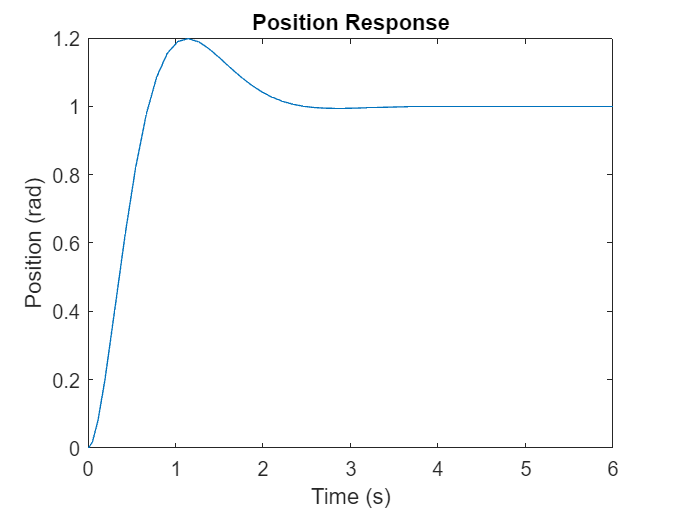

figure
% y(t) plot
plot(out.y.Time, out.y.Data)
xlabel("Time (s)")
ylabel("Position (rad)")
title("Position Response")

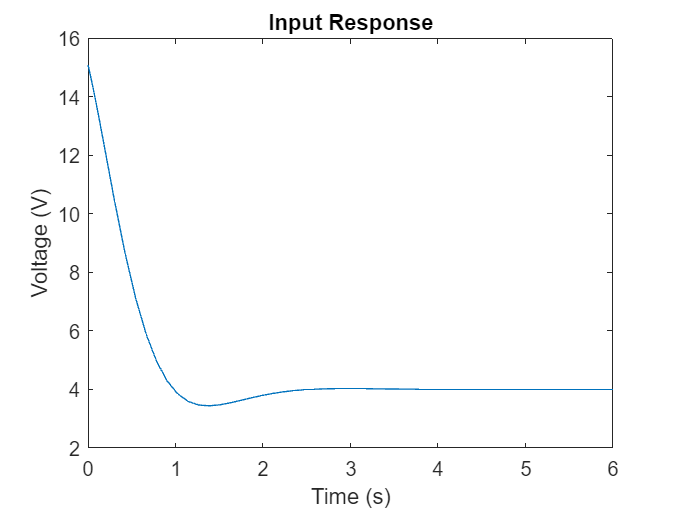


% u(t) plot
plot(out.u.Time, out.u.Data)
xlabel("Time (s)")
ylabel("Voltage (V)")
title("Input Response")

p = -zeroes

p = 1.5000

d0 = (w_n^2)*p

d0 = 12.0000

d1 = 2*zeta*w_n*p + w_n^2

d1 = 14.0000

d2 = 2*zeta*w_n + p

d2 = 5.5000

DesPoles = roots([1 d2 d1 d0])

DesPoles =   -2.0000 + 2.0000i
  -2.0000 - 2.0000i
  -1.5000 + 0.0000i


s_1 = -zeta*w_n + 1i*w_n*sqrt(1-zeta^2)

s_1 = -2.0000 + 2.0000i

K = acker(A, B, DesPoles)

K =    -0.5000    3.0000    6.0000


CG = 1/(C*inv(-A+B*K)*B)

CG = 8.0000

out1 = sim('ICE_6_SVF.slx', 6);

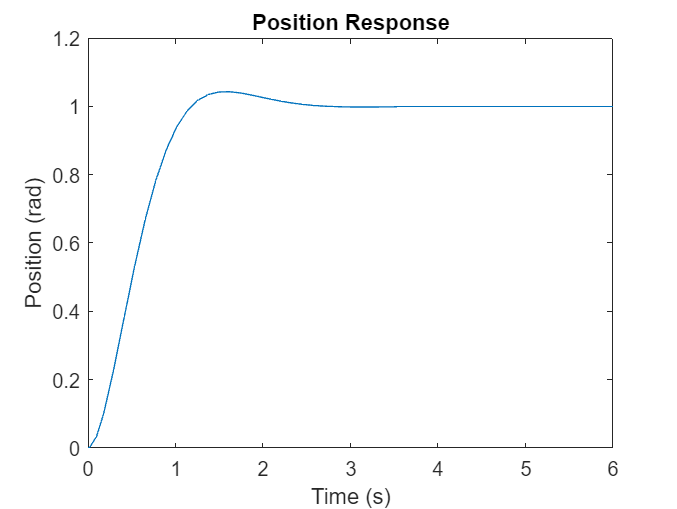

figure
% y(t) plot
plot(out1.y.Time, out1.y.Data)
xlabel("Time (s)")
ylabel("Position (rad)")
title("Position Response")

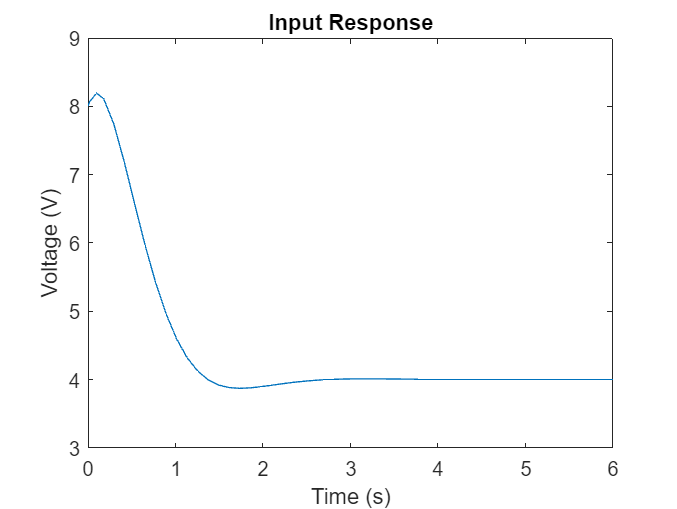


% u(t) plot
plot(out1.u.Time, out1.u.Data)
xlabel("Time (s)")
ylabel("Voltage (V)")
title("Input Response")

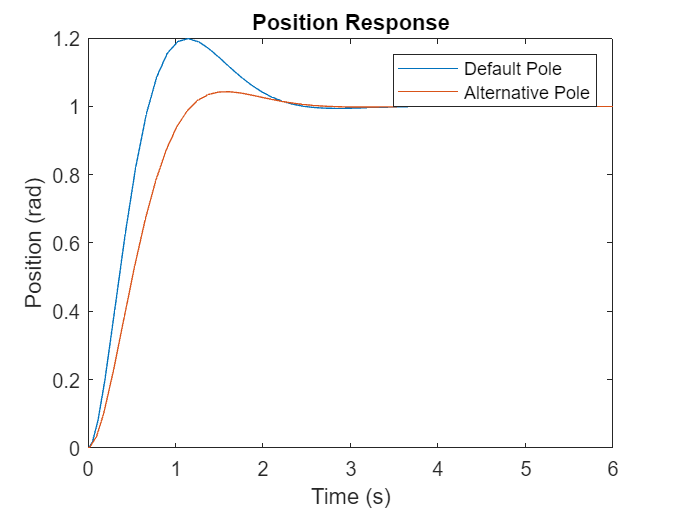

figure
% y(t) plot
plot(out.y.Time, out.y.Data)
hold on
plot(out1.y.Time, out1.y.Data)
hold off
xlabel("Time (s)")
ylabel("Position (rad)")
title("Position Response")
legend("Default Pole", "Alternative Pole")

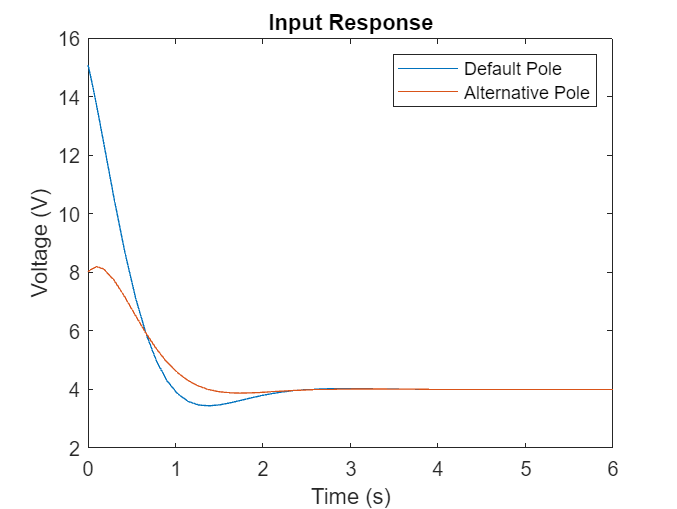


% u(t) plot
plot(out.u.Time, out.u.Data)
hold on
plot(out1.u.Time, out1.u.Data)
hold off
xlabel("Time (s)")
ylabel("Voltage (V)")
title("Input Response")
legend("Default Pole", "Alternative Pole")